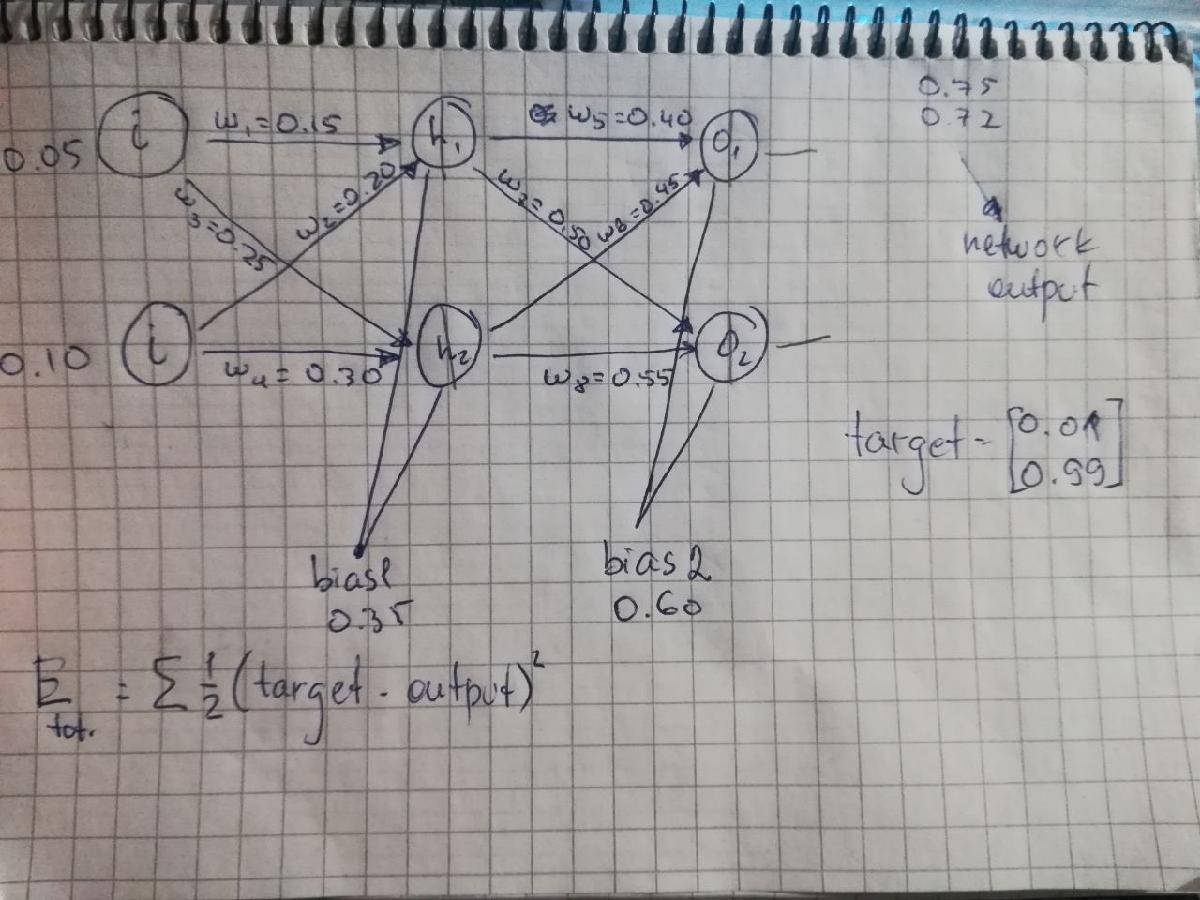

sigmoid = @(x) 1/(1+exp(-x))

sigmoid = function_handle with value:
    @(x)1/(1+exp(-x))


h1 input:

h1i=0.05*0.15+0.10*0.20 + 0.35

h1i = 0.3775

h2 inpuit:

h2i=0.05*0.25+0.10*0.30+0.35

h2i = 0.3925

h1 output:

h1o = sigmoid(h1i)

h1o = 0.5933

h2 output:

h2o = sigmoid(h2i)

h2o = 0.5969

o1 input:

o1i = h1o*0.40+h2o*0.45 + 0.60

o1i = 1.1059

o2 input:

o2i = h1o*0.50 + h2o*0.55 + 0.60

o2i = 1.2249

o1out:

o1out = sigmoid(o1i)

o1out = 0.7514

o2out:

o2out = sigmoid(o2i)

o2out = 0.7729

Let's do a matrix:

weights = [0.15 0.20 0.25 0.30; 0.40 0.45 0.50 0.55];
hs = []


hs =

     []



**Back propagation**


$$\frac{\delta E}{\delta w_5} = \frac{\delta o1out}{\delta o1in}\frac{\delta o1in}{\delta net}\frac{\delta net}{\delta w_5}$$


Updating the last weight matrix:

dw5 = (o1out-0.01)*sigmoid(o1i)*(1-sigmoid(o1i))*h1o

dw5 = 0.0822

dw6 = (o1out - 0.01)*sigmoid(o1i)*(1-sigmoid(o1i))*h2o

dw6 = 0.0827

dw7 = (o2out - 0.99)*sigmoid(o2i)*(1-sigmoid(o2i))*h1o

dw7 = -0.0226

dw8 = (o2out - 0.99)*sigmoid(o2i)*(1-sigmoid(o2i))*h2o

dw8 = -0.0227

w5 = 0.40 - 0.5*dw5

w5 = 0.3589

w6 = 0.45 - 0.5*dw6

w6 = 0.4087

w7 = 0.50 - 0.5*dw7

w7 = 0.5113

w8 = 0.55 - 0.5*dw8

w8 = 0.5614

Updating the first weight matrix:

dpdouth1 = (o1out - 0.01)*sigmoid(o1i)*(1-sigmoid(o1i))*0.4 + (o2out - 0.99)*sigmoid(o2i)*(1-sigmoid(o2i))*0.5

dpdouth1 = 0.0364

dpdouth2 = (o1out - 0.01)*sigmoid(o1i)*(1-sigmoid(o1i))*0.45 + (o2out-0.99)*sigmoid(o2i)*(1-sigmoid(o2i))*0.55

dpdouth2 = 0.0414

dw1 = dpdouth1*sigmoid(h1i)*(1-sigmoid(h1i))*0.05

dw1 = 4.3857e-04

w1 = 0.15-0.5*dw1

w1 = 0.1498

dw2 = dpdouth1*sigmoid(h1i)*(1-sigmoid(h1i))*0.1

dw2 = 8.7714e-04

w2 = 0.20 - 0.5*dw2

w2 = 0.1996

dw3 = dpdouth2*sigmoid(h2i)*(1-sigmoid(h1i))*0.05

dw3 = 5.0218e-04

w3 = 0.25 - 0.5*dw3

w3 = 0.2497

dw4 = dpdouth2*sigmoid(h2i)*(1-sigmoid(h1i))*0.10

dw4 = 0.0010

w4 = 0.30 - 0.5*dw4

w4 = 0.2995